# Rocket flight simulation example

## Input data

% coordinates of the target [km]
xc = 410;
yc = -120;
zc = 0;

% distance to the target [km]
D = sqrt(xc^2 + yc^2)

D = 427.2002

% programmable inclination angle for the starting phase
gamma_pb = deg2rad(24.6);

% yaw angle in t=0 [rad]
psi0 = atan(yc/xc);

% run simulink model
out = sim("simulation_model.slx");


## Data extraction

% data extraction
t = out.tout;

x = out.xyz.Data(:,1);
y = out.xyz.Data(:,2);
z = out.xyz.Data(:,3);

U = out.UVW.Data(:,1);
V = out.UVW.Data(:,2);
W = out.UVW.Data(:,3);

U_dot = out.n.Data(:,1);
V_dot = out.n.Data(:,2);
W_dot = out.n.Data(:,3);
g = out.n.Data(:,4);
n_x = U_dot./g;
n_y = V_dot./g;
n_z = W_dot./g;
n = sqrt(U_dot.^2+V_dot.^2+W_dot.^2)./g;

phi = out.katy.Data(:,1);
theta = out.katy.Data(:,2);
psi = out.katy.Data(:,3);

alfa = out.katy1.Data(:,1);
beta = out.katy1.Data(:,2);
alfa_t = out.katy1.Data(:,3);

delta_w = out.katy_ster.Data(:,1);
delta_k = out.katy_ster.Data(:,2);
delta_w_T = out.katy_ster.Data(:,3);
delta_k_T = out.katy_ster.Data(:,4);

P = out.PQR.Data(:,1);
Q = out.PQR.Data(:,2);
R = out.PQR.Data(:,3);

x_sm = out.x.Data(:,2);
x_sp = out.x.Data(:,1);


% saving data to matrix 
data = [t, x, y, z, U, V, W, U_dot, V_dot, W_dot, g, n_x, n_y, n_z, n,...
phi, theta, psi, alfa, beta, alfa_t, delta_w, delta_k, delta_w_T, delta_k_T, P, Q, R, x_sm, x_sp];

% maximum flight altitude
max(abs(z))

ans = 6.8959e+04

## Plotting results

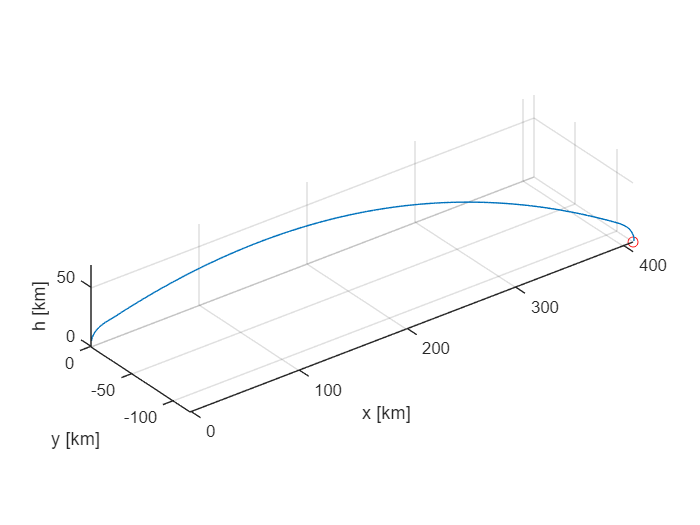

% ploting trajectory of the rocket flight
figure
plot3(x./1000,y./1000,abs(z)./1000,xc,yc,0,'ro')
grid on
axis equal
xlabel('x [km]')
ylabel('y [km]')
zlabel('h [km]')

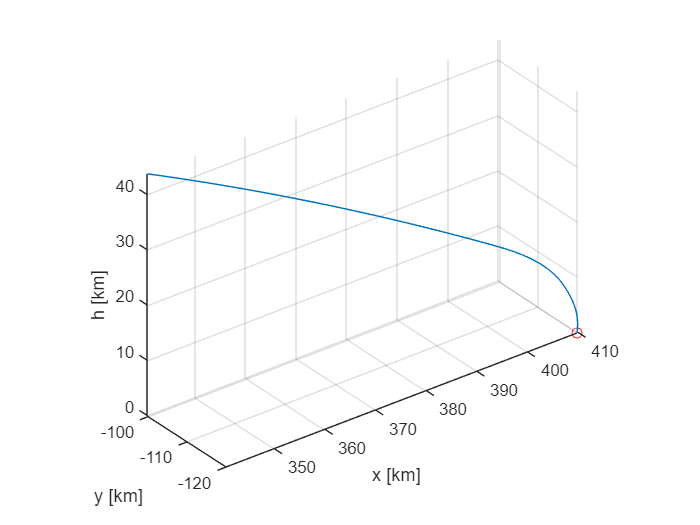


% ploting trajectory of the rocket's final part of flight
figure
plot3(x(2500:end)./1000,y(2500:end)./1000,abs(z(2500:end))./1000,xc,yc,0,'ro')
grid on
axis equal
xlabel('x [km]')
ylabel('y [km]')
zlabel('h [km]')

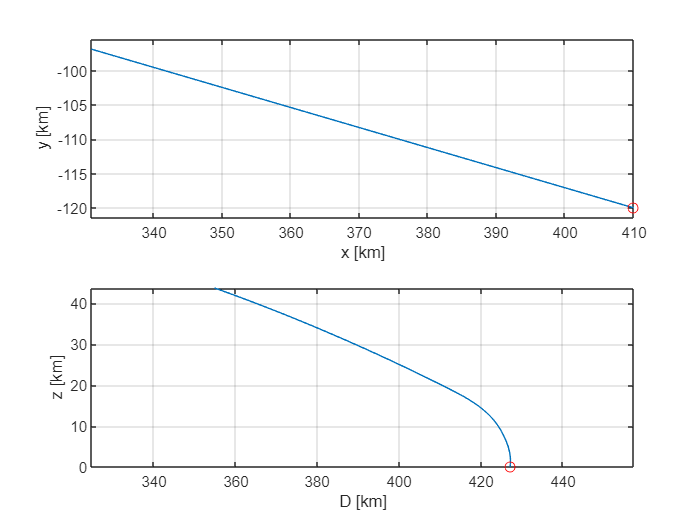


% ploting trajectory of the rocket's final part of flight in 2 dimensions
figure
subplot(2,1,1)
plot(x(2442:end)./1000,y(2442:end)./1000,xc,yc,'ro')
grid on
axis equal
xlabel('x [km]')
ylabel('y [km]')
subplot(2,1,2)
plot(sqrt((x(2500:end)./1000).^2 + (y(2500:end)./1000).^2),abs(z(2500:end))./1000,sqrt(xc^2 + yc^2),0,'ro')
grid on
axis equal
xlabel('D [km]')
ylabel('z [km]')

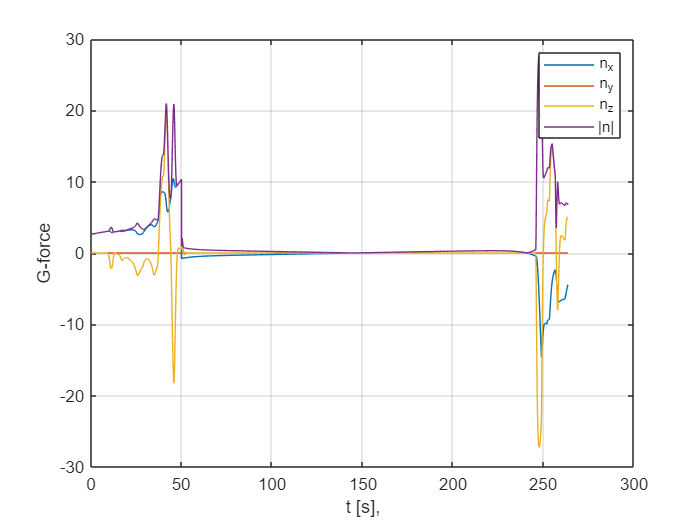


% ploting g-force acting on the object during flight
figure
plot(t,n_x,t,n_y,t,n_z,t,n)
grid on
legend('n_x','n_y','n_z','|n|')
xlabel('t [s]')
ylabel('G-force'); xlabel('t [s],')

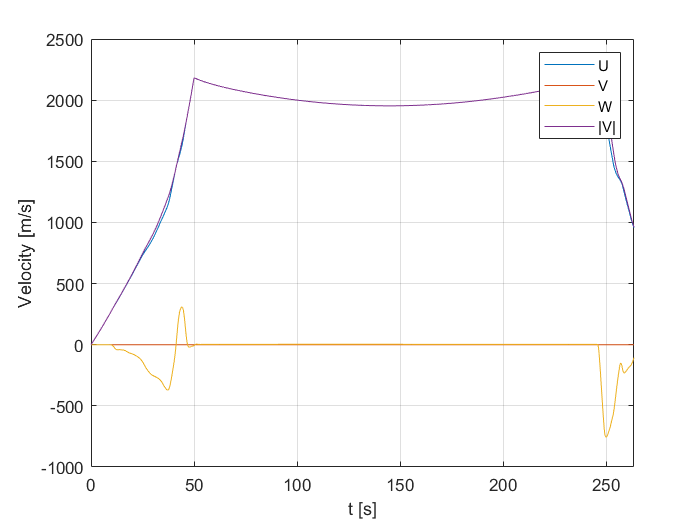


% ploting velocity of the object during flight
figure
plot(t,U,t,V,t,W,t,sqrt(U.^2+V.^2+W.^2))
grid on
legend('U','V','W','|V|')
xlabel('t [s]')
ylabel('Velocity [m/s]')
xlim([0 t(end)])

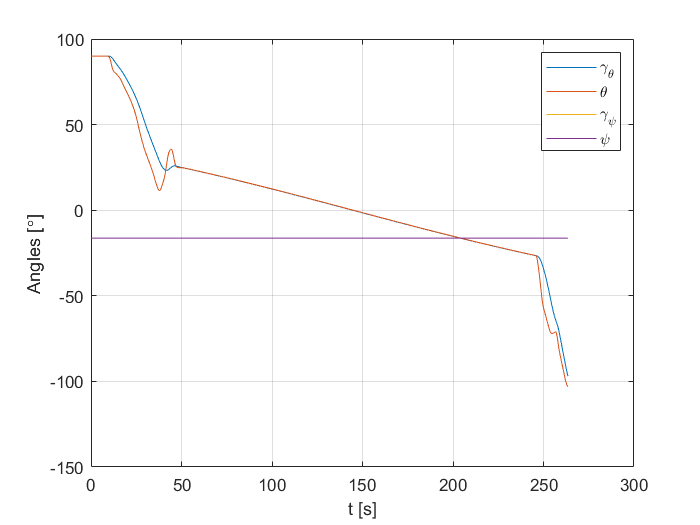


% ploting angles of the object during flight
figure
plot(t,theta-alfa,t,theta,t,psi+beta,t,psi)
grid on
legend('\gamma_\theta','\theta','\gamma_\psi','\psi')
xlabel('t [s]')
ylabel('Angles [\circ]')

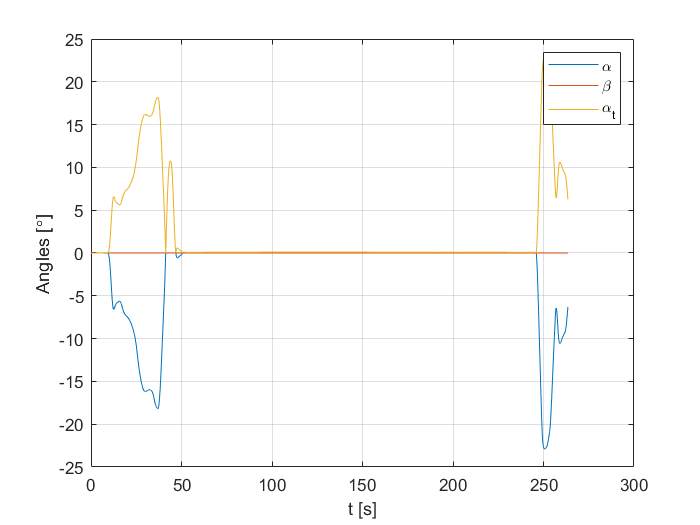


% ploting angles of the object during flight
figure
plot(t,alfa,t,beta,t,alfa_t)
grid on
legend('\alpha','\beta','\alpha_t')
xlabel('t [s]')
ylabel('Angles [\circ]')

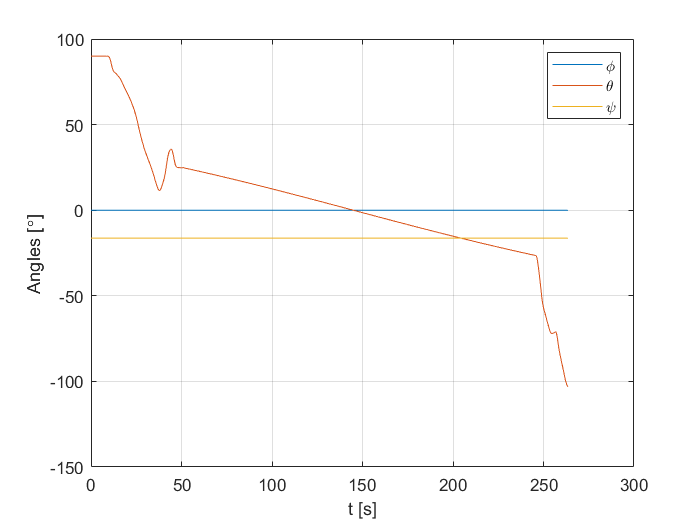


% ploting angles of the object during flight
figure
plot(t,phi,t,theta,t,psi)
grid on
legend('\phi','\theta','\psi')
xlabel('t [s]')
ylabel('Angles [\circ]')

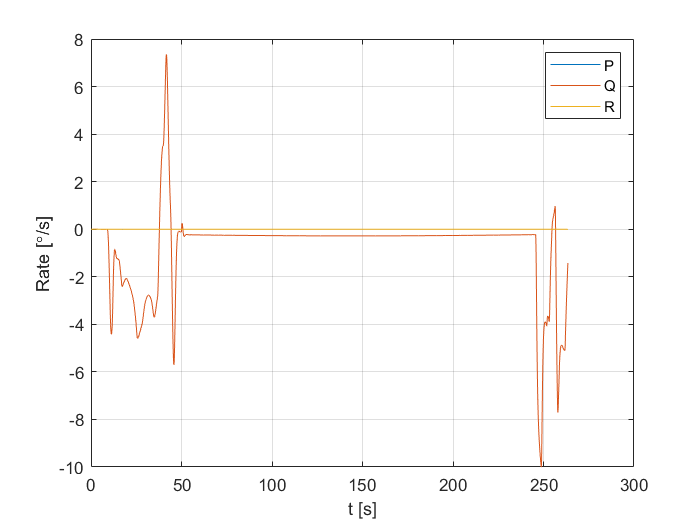


% ploting rate of the object during flight
figure
plot(t,P,t,Q,t,R)
grid on
legend('P','Q','R')
xlabel('t [s]')
ylabel('Rate [\circ/s]')

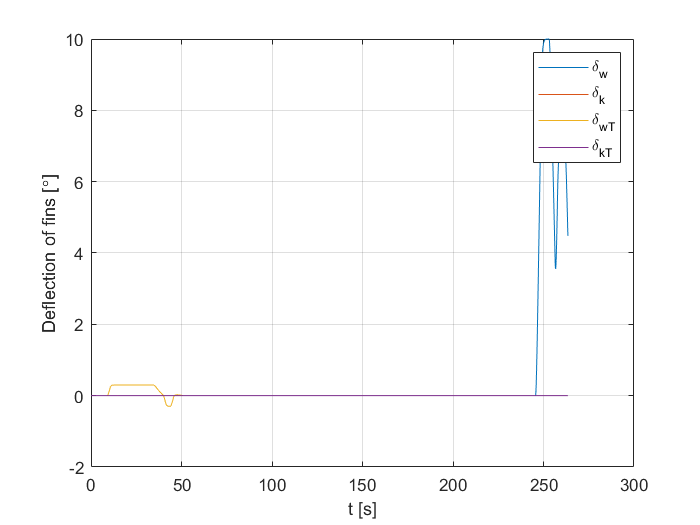


% ploting deflection of fins during flight
figure
plot(t,delta_w,t,delta_k,t,delta_w_T,t,delta_k_T)
grid on
legend('\delta_w','\delta_k','\delta_w_T','\delta_k_T')
xlabel('t [s]')
ylabel('Deflection of fins [\circ]')

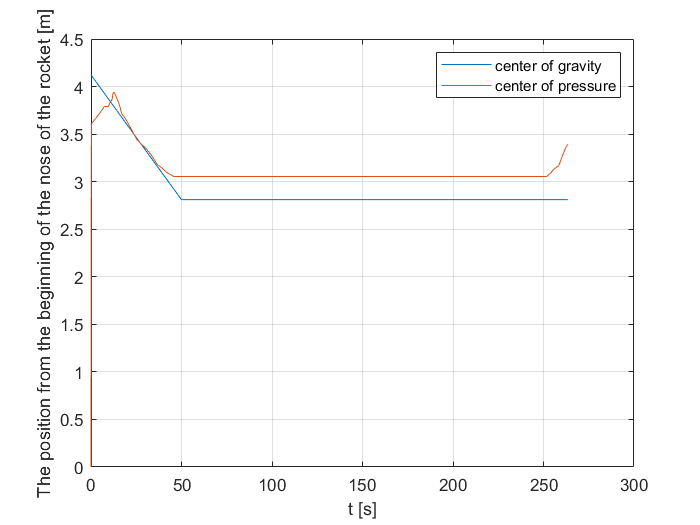


% ploting coordinate center of pressure and center of gravity during flight
figure
plot(t,x_sm, t,x_sp)
grid on
legend('center of gravity','center of pressure')
xlabel('t [s]')
ylabel('The position from the beginning of the nose of the rocket [m]')